# **HW #6 - Genetic Algorithm Crossover Comparison**

### Problem Statement:

Use a genetic algorithm to find the global optimum of the following objective function:


$$f(x,y)=\exp\left( \frac{-\left[ (x-3)^2+(y-3)^2\right]}{5} \right) +
\exp\left( \frac{-\left[ x^2+(y+3)^2\right]}{5} \right) + 
0.2\left[ \cos\left(\frac{x\pi}{2}\right) + \cos\left(\frac{y\pi}{2}\right)\right] +
5$$


objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;

Mathematically we know this function has a maximum height of 1.6903 in the range of -5 to 5 for x and y.

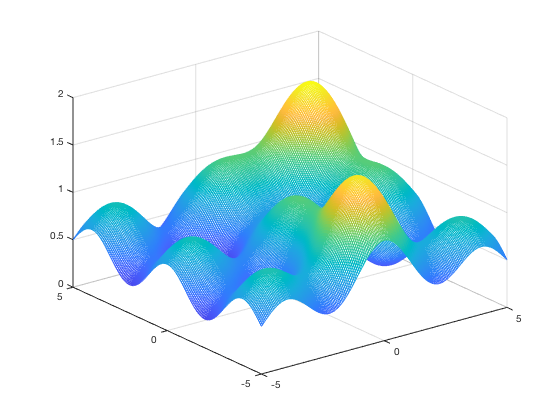

[x,y]=meshgrid(-5:0.05:5);
mesh(x,y,objf(x,y));

### Methods:

- Representation: Binary

- Selection: Elitist, Rank Selection

- Mating/Variation: Single Point Binary Crossover, Uniform Crossover

### Initialize Parameters

For a genetic algorithm, the important parameters are population size, number of generations to execute, fraction of population seleected for mating, the data representation, and the range of data.

clc;
clear;
    % ***** User Changable Variables ***** %
objf = @(x,y) exp(-((x-3).^2+(y-3).^2)./5) + 0.8.*exp(-(x.^2+(y+3).^2)./5) + 0.2*(cos(x.*pi./2)+cos(y.*pi./2)) + 0.5;

pop = 40;               %population size
gen = 200;              %number of generations
pcntsel = 0.5;          %fraction of candidated selected for next generation

precision = 8;          %precision of real number represenation (ex. 8 -> 8-bit represenation)
range = [-5 5; -5 5];   %bounds for input variables

% ***** Calculations ***** %
mu = round(pcntsel*pop);    %number of parents selected
lambda = pop - mu;          %number of new candidates in each generation (children)



### Generate Initial Population

Generally, the initial population is generated randomly within specified ranges. 

for iteration = 1:5

### Genetic Algorithm

xlabel = 'Generation'

ylabel = 'Fitness Score'

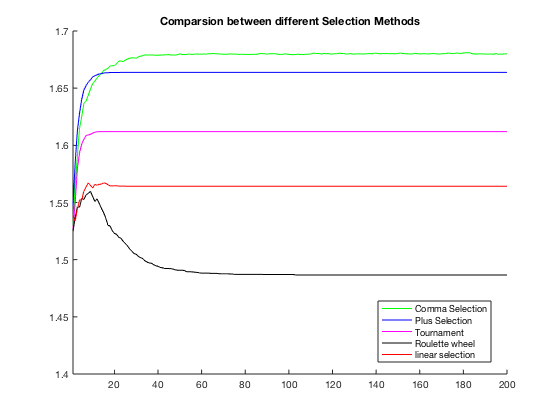

    array = zeros(gen,1);
    for t = 1:gen
        
        candidate.binx = rand(pop,precision)>0.5;   %generate binary representation
        candidate.biny = rand(pop,precision)>0.5;
        
        bestGenArray = zeros(200,1);
        
        for i = 1:gen
    
        % ********* Convert Representation ****** %
            candidate.x = (range(1,1)-range(1,2))*(bi2de(candidate.binx)/(2^precision-1))+range(1,2);
            candidate.y = (range(2,1)-range(2,2))*(bi2de(candidate.biny)/(2^precision-1))+range(2,2);
        % *************************************** %
    
        % ********* Get Fitness ***************** %
            candidate.fit = objf(candidate.x,candidate.y);
        % *************************************** %
    
        % ********* Selection ******************* %
        switch iteration
            case{1}
                [newCandidate,bestGenArray] = comma_selection(candidate,bestGenArray,mu,i); %parent will die
                [newCandidate] = crossover(newCandidate, mu, precision, lambda);
            case{2}                
                [newCandidate,bestGenArray] = plus_selection(candidate,bestGenArray,mu,i); %parent will live
            case{3}
                [newCandidate,bestGenArray] = tournament_s(candidate,bestGenArray,mu,i,pop);
            case{4}
                [newCandidate, bestGenArray] = Roulette_Wheel(candidate,bestGenArray,pop,mu,i);
            case{5}
                [newCandidate,bestGenArray] = lrs(candidate,bestGenArray,pop,mu,i);
        end
        

   
        % *************************************** %
    
        % ********* Create Offspring ************ %
           
         if iteration>1
            [newCandidate] = u_crossover(newCandidate, mu, precision, lambda);
         end

      
        % *************************************** %
    
        % ********* Next Generation ************* %
            candidate = newCandidate;
        % *************************************** %
        end
        array = array + bestGenArray;

    end
    array = array./t;
   
    switch iteration 
        case {1}
            plotarrayA = array; 
        case {2}
            plotarrayB = array;
        case {3}
            plotarrayC = array;
        case {4}
            plotarrayD = array;  
        case {5}
            plotarrayE = array;
    end
end



%plot

figure;
hold on;
axis([1 gen 1.4 1.7]);
title("Comparsion between different Selection Methods");


% data points 
data_points = 1:200;

% Create array    
A1 = plotarrayA(data_points);
A2 = plotarrayB(data_points);
A3 = plotarrayC(data_points);
A4 = plotarrayD(data_points);
A5 = plotarrayE(data_points);

% plot 
plot(data_points,A1,'color','g');
plot(data_points,A2,'Color','b');
plot(data_points,A3,'Color','m');
plot(data_points,A4,'Color','k');
plot(data_points,A5,'Color','r');

xlabel = ('Generation')
ylabel = ('Fitness Score')
legend({'Comma Selection','Plus Selection','Tournament ','Roulette wheel','linear selection '},'Location','best')
hold off;


Discussion:  

Genetic algorithms (GA) are used to to solve combinatorial optimization problems. One of the problems in using genetic algorithms is the choice of crossover operator. The GA is applied to the optimization problem. 

The initial populations are generated randomly. The quality of this population is poor and one way to improve it is to incorporate some chromosomes generated by priority rules.

The genetic algorithms typically use the following types of operators: Selection: Operator for selecting individuals for reproduction according to their fitness:

    Crossover (Sexual Recombination): Operator of merging the genetic information of two individuals. In many respects the effectiveness of crossover is depended on coding.

    Mutation (Asexual): In real evolution, the genetic material can by changed randomly by erroneous reproduction or other deformations of genes, e.g. by gamma radiation. In genetic algorithms, mutation realized as a random deformation of alleles with a certain probability. 

After reproduction, crossover may proceed in two steps. First, members of the newly reproduced chromosomes in the mating pool are mated at random. Second, each pair of chromosomes undergoes crossover as follows: an integer position k along the chromosome is selected uniformly at random between 1 and the chromosome length l. Two new chromosomes are created swapping all the genes between k+1 and l.

In uniform crossover, a value of the first parent’s gene is assigned to the first offspring and the value of the second parent’s gene is to the second offspring with a probability value. From the HW 5, we can obtain that the uniform crossover displays better result. Therefore, we have used uniform crossover for this homework. 

We’ll initialize a population of 40 candidate solutions uniformly at random from [-5 -5;-5 -5]. A comparison of different selection methods has shown on the figure 1. The results, averaged over 200 trials, favor the use of comma selection in this case. 		

Roulette Wheel selection evidenced the slowest rate of improvement, while  linear selection found better solutions on average than did Roulette Wheel  selection method. Tournament selection method stands middle among all of them. 

Between comma and plus selection, comma selection shows the overall better performance that menas its searches for the solution over the space.

In conclusion, Comma selection method shows better performance for this problem. 

function [n_generation] = u_crossover(n_generation, mu, precision, lambda)
% Ttile: Uniform crossover algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation
        
        % initialization 

        ch1x = zeros(1,precision);
        ch2x = zeros(1,precision);
        ch1y = zeros(1,precision);
        ch2y = zeros(1,precision);
        
       
    for i=1:lambda
        
        %Mask generation 
        mask = randi([0 1], 1, precision); 
        
        % Parents selection 
        p_index1 = 0;
        p_index2 = 0;
        
        %pick up the parent in random
        while p_index1 == p_index2
            p_index1 = randi([1 mu], 1, 1);
            p_index2 = randi([1 mu], 1, 1);
        end
        
        % first parent
        p_1x = n_generation.binx(p_index1,:);
        p_1y = n_generation.biny(p_index1,:);
        % second parent 
        p_2x = n_generation.binx(p_index2,:);
        p_2y = n_generation.biny(p_index2,:);
        
       % child creation 
        for j = 1 : precision
            if mask (j) == 1
                ch1x(j) = p_1x(j);
                ch1y(j) = p_1y(j);
                ch2x(j) = p_2x(j);
                ch2y(j) = p_2y(j); 
            else
                ch1x(j) = p_2x(j);
                ch1y(j) = p_2y(j);
                ch2x(j) = p_1x(j);
                ch2y(j) = p_1y(j); 
            end
        
        
        end
        % next generation 
        n_generation.binx(mu+i,:) = ch1x(1,:);
        n_generation.biny(mu+i,:) = ch1y(1,:);
        n_generation.binx(mu+i,:) = ch2x(1,:);
        n_generation.biny(mu+i,:) = ch2y(1,:);
    end
        
   

end

% Linear selection 
function [newCandidate,bestGenArray] = lrs(candidate,bestGenArray,pop,mu,i)
% Ttile: Linear search selection algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation, array 
        
     % initialization 
    
    etaplus = 1.7;
    etaminus = 2 - etaplus;
    
    [~,I]=sort(candidate.fit,'descend');
    
    % best candidate 
    bestGenArray(i)= candidate.fit(I(1,:),:);
    
    prop = zeros(pop,1); % initialization
    
    for j = 1:pop
       prop(j,:) = (etaplus - (((etaplus-etaminus)*(j-1))/(pop-1)))/pop;% formula from lecutre
    end
    
    prop = cumsum(prop);
   
    k = 1;
    while k <= mu
        sel = rand(1,1);
        for l = 1:pop
            if prop(l,:) >= sel
              newCandidate.binx(k,:) = candidate.binx(I(l),:);
              newCandidate.biny(k,:) = candidate.biny(I(l),:);
              k = k + 1;
              break;
            end
        end   
    end 
             
end


% Tournament selection
function [newCandidate, bestGenArray]=tournament_s(candidate,bestGenArray,mu,i,pop)
% Ttile: Tournament selection algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation, array 
        
     % initialization     
    [~,I]=sort(candidate.fit,'descend');
    
    % best candidate 
    bestGenArray(i)= candidate.fit(I(1,:),:);
    
    number = [];
    % algorithm implementation 
    for j = 1:mu
        
        pick1 = 0;
        pick2 = 0;
        
        while pick1 == pick2 || ismember(pick1,number) || ismember(pick2,number)
            pick1 = randi([1 pop],1,1);
            pick2 = randi([1 pop],1,1);
        end
        
        if candidate.fit(pick1,:) > candidate.fit(pick2,:)
            newCandidate.binx(j,:) = candidate.binx(pick1,:);
            newCandidate.biny(j,:) = candidate.biny(pick1,:);
            number = [number, pick2];
        else
            newCandidate.binx(j,:) = candidate.binx(pick2,:);
            newCandidate.biny(j,:) = candidate.biny(pick2,:);
            number = [number, pick1];

        end
        
    end


end

% Proportional (Roulette Wheel) Selection
function [newCandidate, bestGenArray] = Roulette_Wheel(candidate,bestGenArray,pop,mu,i)
 % Ttile: Proportional (Roulette Wheel) Selection algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation, array 
        
     % initialization   
  fitsum = sum(candidate.fit);       
  [cfit, I]= sort(candidate.fit,'descend');
  
   % best candidate 
  bestGenArray(i) = candidate.fit(I(1,:),:);
            
  candidate.p = cfit./fitsum;
  candidate.sp = cumsum(candidate.p);
          
  %selection
  for j = 1:mu
      sel=rand;
      for k = 1:pop
          if candidate.sp(k) >= sel
              newCandidate.binx(j,:) = candidate.binx(I(k),:);
              newCandidate.biny(j,:) = candidate.biny(I(k),:);
              break;
          end
      end
  end
    
end


% Plus Selection Algorithm Implementation 
function [newCandidate,bestGenArray] = plus_selection(candidate, bestGenArray, mu, i)
% Ttile: Plus selection algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation, array
        
    % initialization 

    [~,I]=sort(candidate.fit,'descend');
    
    %best value for each generation
    bestGenArray(i)= candidate.fit(I(1,:),:);
    
    newCandidate.binx(1:mu,:) = candidate.binx(I(1:mu),:);
    newCandidate.biny(1:mu,:) = candidate.biny(I(1:mu),:);

end


% Comma selection algorithm 

function [newCandidate,bestGenArray] = comma_selection(candidate, bestGenArray, mu, i)
    
    % Ttile: Comma selection algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation, array
        
    % initialization
    [~,I]=sort(candidate.fit,'descend');
    bestGenArray(i)= candidate.fit(I(1,:),:);
    
    newCandidate.binx(1:mu,:) = candidate.binx(I(1:mu),:);
    newCandidate.biny(1:mu,:) = candidate.biny(I(1:mu),:);
    
end


function [newCandidate] = crossover(newCandidate, mu, precision, lambda)
% Ttile: Crossover selection algorithm implementation

        % input: mu->number of parents selected, precision-> precision of real number represenation
        % lambda-> number of new candidates in each generation (children)
        % O/P: n_generation, array
    % parents die each generation and a surplus of offspring must be created
    
        Child1x = zeros(1,precision);
        Child2x = zeros(1,precision);
        Child1y = zeros(1,precision);
        Child2y = zeros(1,precision);
        
        count = 1;
        
        
    while count <= lambda
        
        dieOrLive = randi([0 1],1,1);
        
        %binary mask
        mask = randi([0 1], 1, precision); 
        
        % random Parents selection 
        ParentIndex1 = 0;
        ParentIndex2 = 0;
        
        %random Parents selection 
        while ParentIndex1 == ParentIndex2
            ParentIndex1 = randi([1 mu], 1, 1);
            ParentIndex2 = randi([1 mu], 1, 1);
        end
        
        
        Parent1x = newCandidate.binx(ParentIndex1,:);
        Parent1y = newCandidate.biny(ParentIndex1,:);

        Parent2x = newCandidate.binx(ParentIndex2,:);
        Parent2y = newCandidate.biny(ParentIndex2,:);
        
       
        for j = 1 : precision
            if mask (j) == 1
                Child1x(j) = Parent1x(j);
                Child1y(j) = Parent1y(j);
                Child2x(j) = Parent2x(j);
                Child2y(j) = Parent2y(j); 
            else
                Child1x(j) = Parent2x(j);
                Child1y(j) = Parent2y(j);
                Child2x(j) = Parent1x(j);
                Child2y(j) = Parent1y(j); 
            end
        
        
        end
        
        if dieOrLive == 0
            newCandidate.binx(ParentIndex1,:) = rand(1,precision)>0.5;   %generate binary representation
            newCandidate.biny(ParentIndex1,:) = rand(1,precision)>0.5;
            newCandidate.binx(ParentIndex2,:) = rand(1,precision)>0.5;   %generate binary representation
            newCandidate.biny(ParentIndex2,:) = rand(1,precision)>0.5;
        end
            
        newCandidate.binx(mu+count,:) = Child1x(1,:);
        newCandidate.biny(mu+count,:) = Child1y(1,:);
        count = count+1;
        newCandidate.binx(mu+count,:) = Child2x(1,:);
        newCandidate.biny(mu+count,:) = Child2y(1,:);
        count = count+1;
    end


    

end


